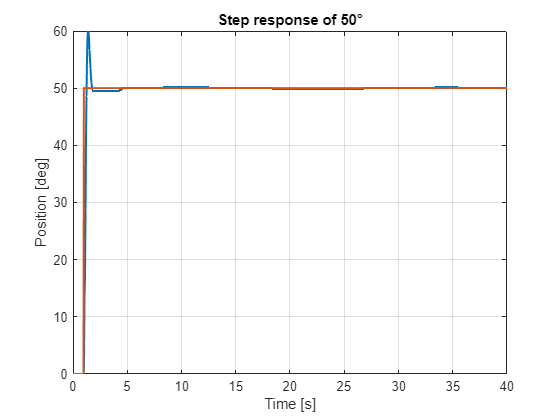

step_gain = 50;

model = 'PID_validation_3_3_2';

load_system(model)

set_param(model,'SimulationCommand','disconnect')  % pulizia

slbuild(model)  % rebuild

set_param(model,'SimulationCommand','connect')
set_param(model,'SimulationCommand','start')

while ~strcmpi(status, 'stopped')
    pause(0.5);
    status = get_param(model, 'SimulationStatus');
end           


t_3_3_2_50deg = out_real_system.theta_h_encoder.time;

th_3_3_2_50deg = out_real_system.theta_h_encoder.signals.values;

% Create plots
% Define the step amplitude vector

figure; 
plot(t_3_3_2_50deg,th_3_3_2_50deg, 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');

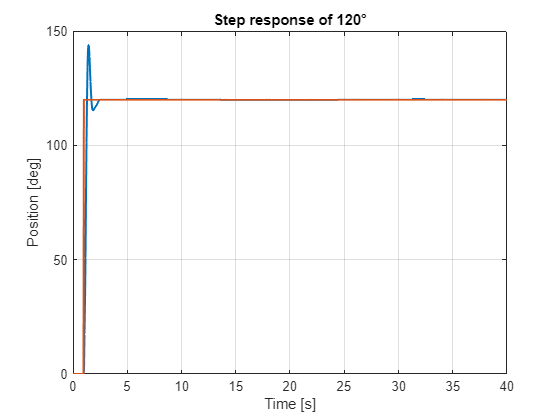

% Create plots

step_gain = 120;

load_system(model)

set_param(model,'SimulationCommand','disconnect')  % pulizia

slbuild(model)  % rebuild

set_param(model,'SimulationCommand','connect')
set_param(model,'SimulationCommand','start')

while ~strcmpi(status, 'stopped')
    pause(0.5);
    status = get_param(model, 'SimulationStatus');
end           


t_3_3_2_120deg = out_real_system.theta_h_encoder.time;

th_3_3_2_120deg = out_real_system.theta_h_encoder.signals.values;

% Create plots
% Define the step amplitude vector

figure; 
plot(t_3_3_2_120deg,th_3_3_2_120deg, 'LineWidth', 1.5);
grid on;
title(sprintf('Step response with T= %d°', T));
xlabel('Time [s]');
ylabel('Position [deg]');